# Лабораторная работа 7-8

## 2D-графики функций

## Пример 6.7

Вывести график функции в полярных координатах.

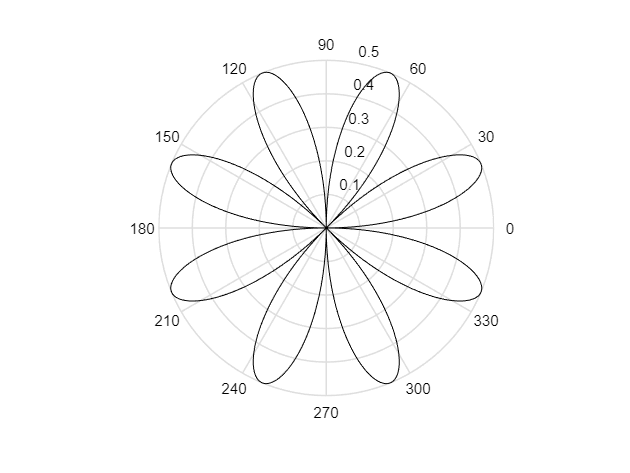

t = 0:.01:2 * pi;
r = sin(2 * t).*cos(2 * t);
polar(t, r, 'k')

## Пример 6.9

Вывести график функции, заданной параметрически: x(t)=sin(2t), y(t)=cos(t), 0 ≤ t ≤ 2π.

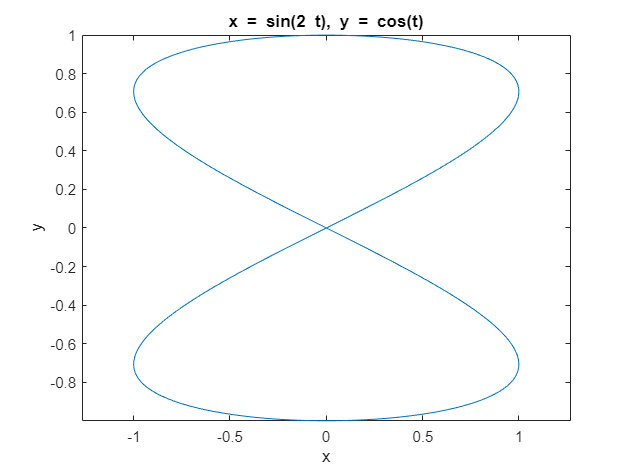

x = @(t) sin(2 * t);
y = @(t) cos(t);
ezplot(x, y, [0,2 * pi])

% ezplot(funx, funy, uinterval) строит график на указанном интервале. Задаю интервал как двухэлементный вектор в виде [umin umax].

## Пример 6.11

Построить траекторию движения точки в течение 10 секунд, координаты которой изменяются по закону, задаваемому функциями x, y.

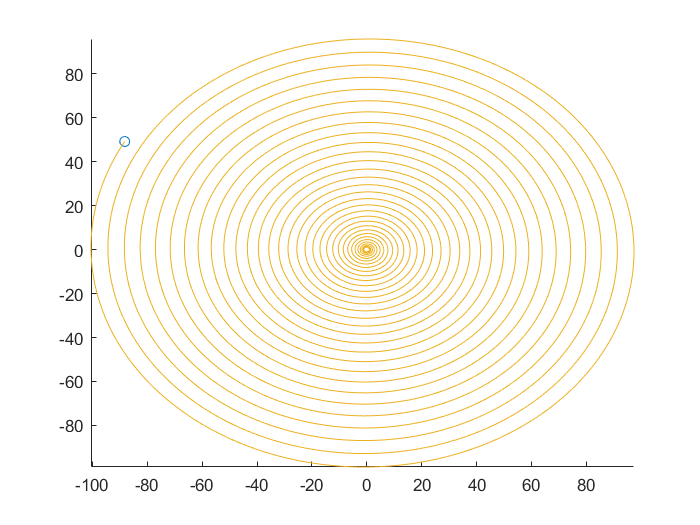

t = 0:0.001:10;
x = (1 + t.^2).*sin(20 * t);
y = (1 + t.^2).*cos(20 * t);
comet(x, y)

% comet(x, y) отображает график траектории движения точки, координаты
% которой задаются массивами x, y

## Диаграммы и гистограммы

## Пример 6.13

Диаграмма с областями

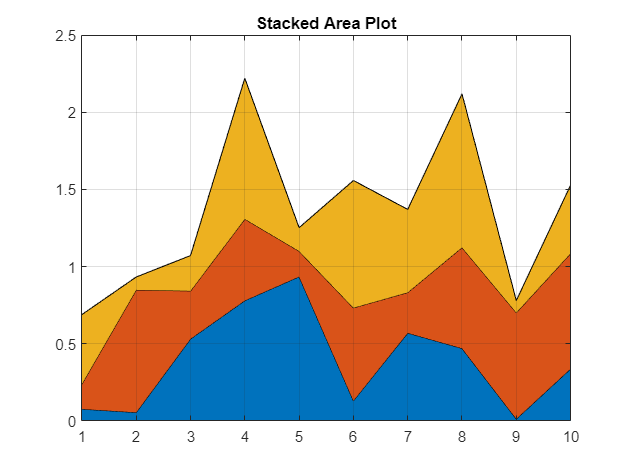

area(rand(10, 3))
grid on
colormap summer
set(gca, 'Layer', 'top');
title 'Stacked Area Plot'

% area(Y) - отображает Y по неявному множеству координат x и заполняет зоны
% между кривыми. Если Y - это вектор, то координаты x будут ранжироваться
% от 1 до длины Y. Если Y - это матрица, координаты x будут варьироваться
% от 1 до числа строк в Y.
% rand(sz1, sz2) - возвращает матрицу sz1 на sz2, заполненную случайными
% числами.
% set - устанавливает свойства для графических объектов: set(H,Name,Value).
% gcs - текущие оси или графики

## Пример 6.14

Столбчатая диаграмма матричных данных.

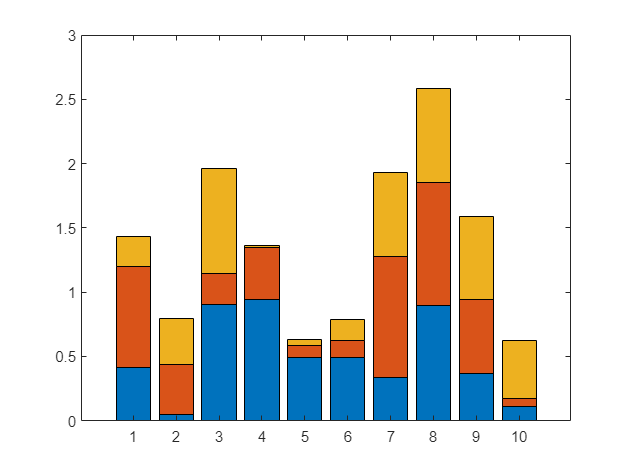

d = rand(10, 3);
bar(d, 'stacked')

% bar(d, 'stacked') - создает столбчатую диаграмму с одним столбцом для
% каждого элемента в d, если d - матрица m на n, то создает группу
% столбцов, задается стиль

## Пример 6.16

Круговая диаграмма

x = rand(1, 15)

x =     0.2077    0.3012    0.4709    0.2305    0.8443    0.1948    0.2259    0.1707    0.2277    0.4357    0.3111    0.9234    0.4302    0.1848    0.9049


explode = x./sum(x) < .05

explode = 1×15 logical array
   1   1   0   1   0   1   1   1   1   0   0   0   0   1   0


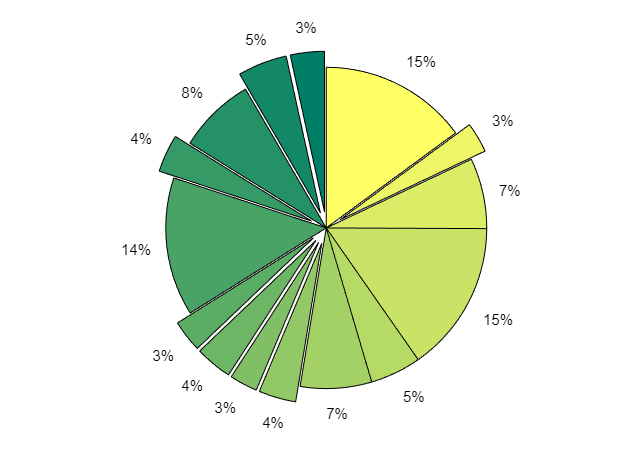

pie(x, explode)

% смещает части круговой диаграммы пирога, explode - вектор или матрица из
% нулей и не нулей, которые соответствуют x. Эта функция смещает срезы для
% ненулевых элементов только в explode
% pie(X) рисует круговую диаграмму, используя данные из x. Каждый сектор круговой диаграммы представляет элемент в x.
% Если sum(x) ≤ 1, то значения в x напрямую определяют площади секторов круговой диаграммы. pie рисует только частичный круг, если sum(x) < 1.
% Если sum(x) > 1, функция pie нормализует значения по x/sum(x), чтобы определить площадь каждого сектора круговой диаграммы.

## 3D-графики функций и поверхностей

## Пример 6.23

Построить винтовую линию.

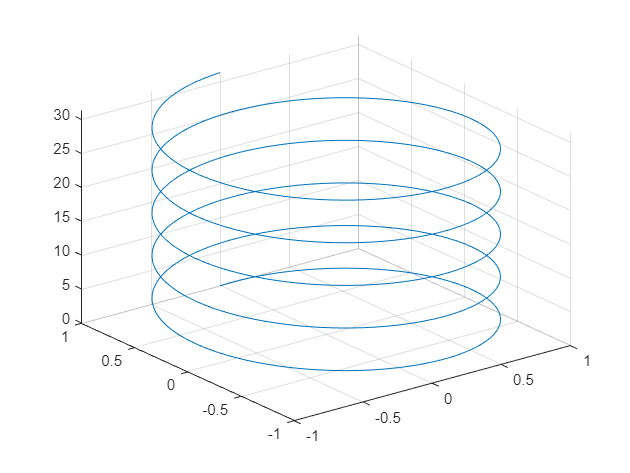

t = 0:pi / 50:10 * pi ;
x = sin(t);
y = cos(t);
plot3(x, y, t);
grid on

% plot3 - 3D-графики

## Пример 6.24

Функция ezplot3.

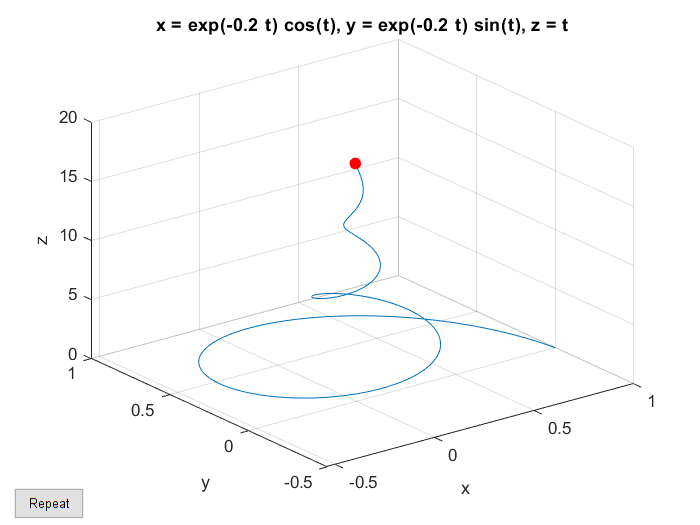

r1 = @(t) exp(-0.2 * t).*cos(t);
r2 = @(t) exp(-0.2 * t).*sin(t);
r3 = @(t) t;
ezplot3(r1, r2, r3, [0, 20], 'animate')

% ezplot3 - легко используемая функций, строющая 3D-графики параметрически
% заданных кривых

## Пример 6.27

Построение освещенных поверхностей.

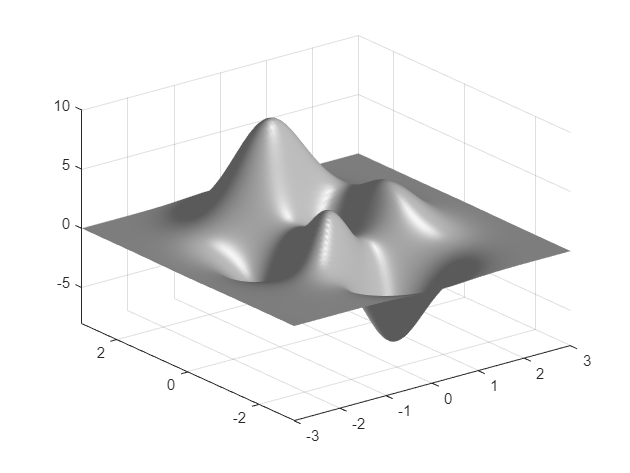

[x, y, z] = peaks(100);
surfl(x, y, z)
shading interp
colormap(gray(1000))
axis([-3, 3, -3, 3, -8, 10])

% peaks выбирает случайные значения?

## Пример 6.30

Построение параметрически заданной поверхности.

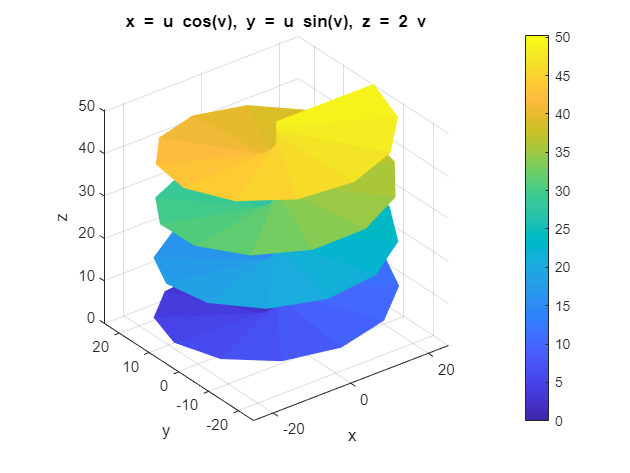

ezsurf('u*cos(v)', 'u*sin(v)', '2*v', [0,8 * pi])
axis equal
colormap default
colorbar
shading flat

% ezsurf - 3D-график для поверхностей

## Пример 6.31

Построение параметрически заданной поверхности.

x = @(t, phi) (10 + 4*cos(t)).*cos(phi);
y = @(t, phi) (10 + 4*cos(t)).*sin(phi);
z = @(t, phi) 4 * sin(t)

z = function_handle with value:
    @(t,phi)4*sin(t)


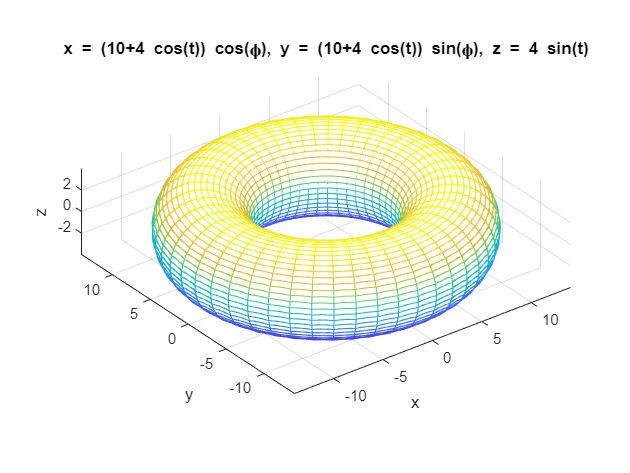

ezmesh(x, y, z)
axis equal

% ezmesh - отображает параметрически определенный график x = funx(u,v), y =
% funy(u,v), z = funz(u,v) на интервале [-2 * pi; 2 * pi]

## Измение свойств линии

## Пример 6.33

Изобразить график красной сплошной линией, на которой в дискретных вычисляемых точках проставлены черные квадраты.

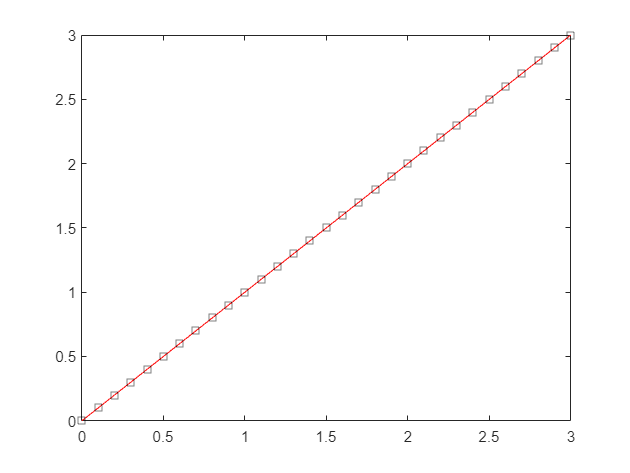

x = 0:0.1:3;
plot(x, x, 'r', x, x, 'ks')

## Пример 6.34

Изменить толщину линии графика

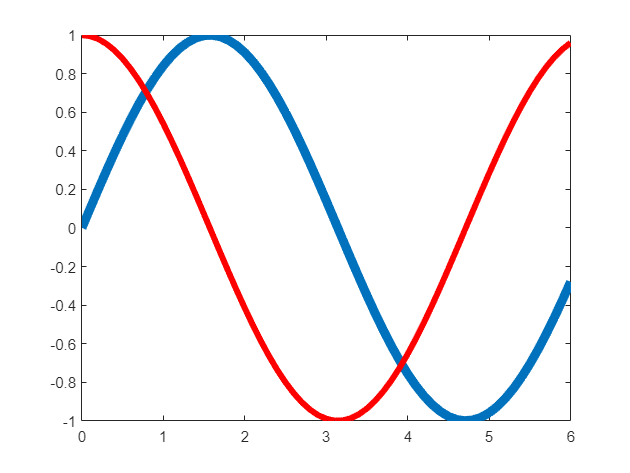

x = 0:0.1:6;
hl = plot(x, sin(x));
set(hl, 'LineWidth', 6);
hold on
plot(x, cos(x), 'r', 'LineWidth', 4);
hold off

## Задания

## Задание 6.1

Построить график функции в полярных координатах:

% а)
t = 0:0.01:2 * pi;
y = sin(2 * t).*cos(2 * t);
polar(t, y, 'k')

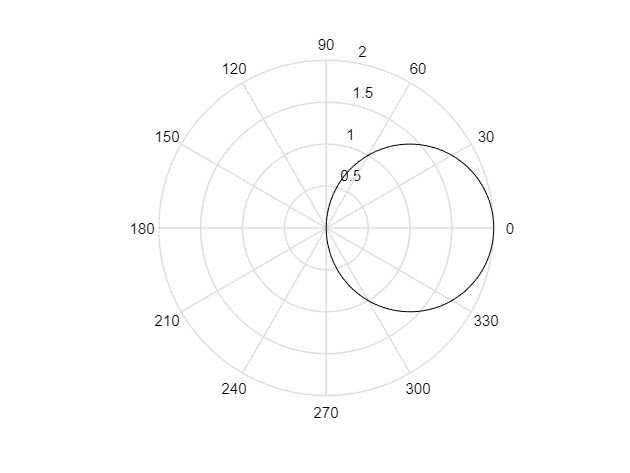

% б)
phi = -pi * 2:0.01:pi * 2;
r = 2 * cos(phi);
polar(phi, r, 'k')

## Задание 6.3

Представить результат случайных измерений трех величин за четыре момента времени в виде матрицы случайных значений 3 × 4. 

Отобразить результат: 

а) в виде столбчатой диаграммы сгруппированных данных с перекрывающимися столбцами; 

б) в виде столбчатой диаграммы с накоплением; 

в) в виде диаграммы с областями.

x = rand(3, 4)

x =     0.9797    0.2581    0.2622    0.2217
    0.4389    0.4087    0.6028    0.1174
    0.1111    0.5949    0.7112    0.2967


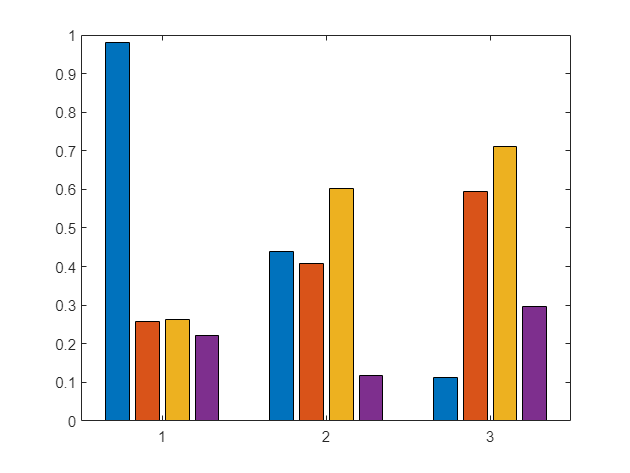

% а)
bar(x)

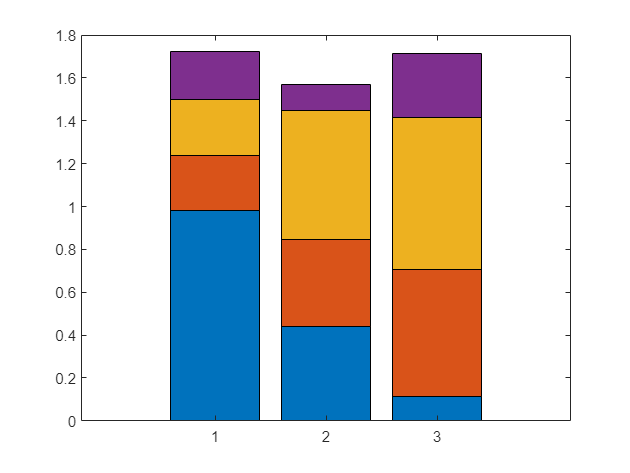


% б)
bar(x, 'stacked')

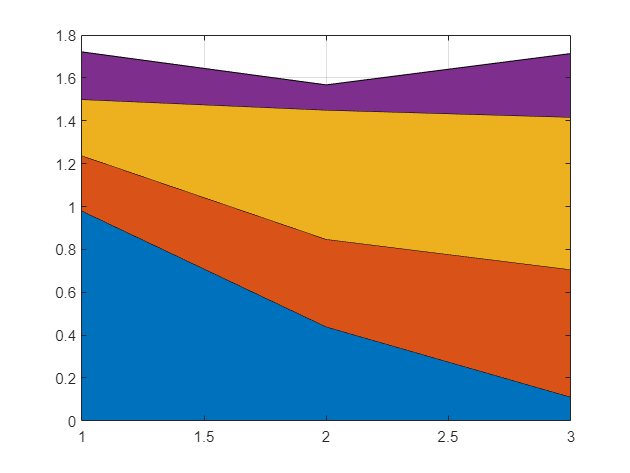


% в)
area(x)
grid on

## Задание 6.10

Построить график функции, заданной параметрически

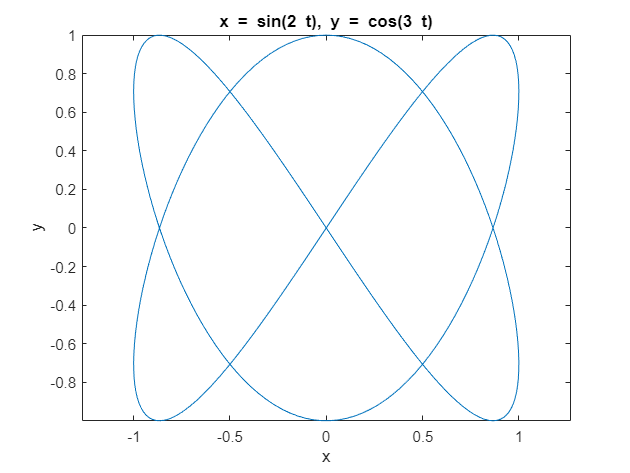

% а)
t = -2 * pi:0.01:2 * pi;
x = @(t) sin(2 * t);
y = @(t) cos(3 * t);
ezplot(x, y, [0,2 * pi])

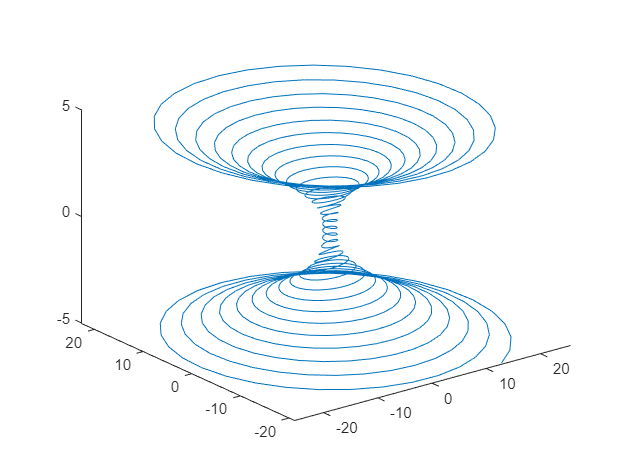


% б)
t = -5:0.01:5;
x = (1 + t.^2) .* sin(20 * t);
y = (1 - t.^2) .* cos(20 * t);
plot3(x, y, t)

## Задание 6.11

Построить прозрачную каркасную поверхность фигуры, заданной соотношениями.

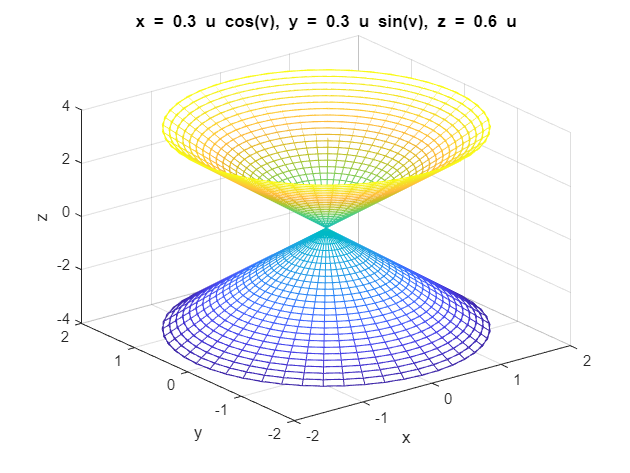

% а)
x = @(u, v) 0.3 * u .* cos(v);
y = @(u, v) 0.3 * u .* sin(v);
z = @(u, v) 0.6 * u;
ezmesh(x, y, z)
ezsurf('0.3 * u .* cos(v)', '0.3 * u .* sin(v)', '0.6 * u', [-2 * pi, 2 * pi])

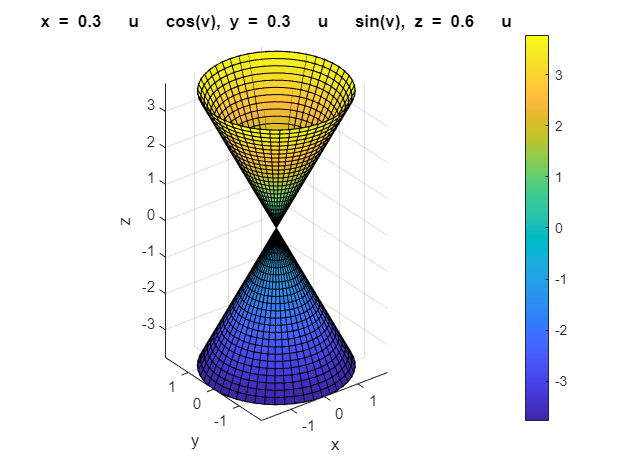

axis equal
colormap default
colorbar
axis equal
% б)
x = @(u, v) cos(u) .* cos(v);
y = @(u, v) 0.7 * cos(u) .* sin(v);
z = @(u, v) 0.8 * sin(u);
ezmesh(x, y, z)

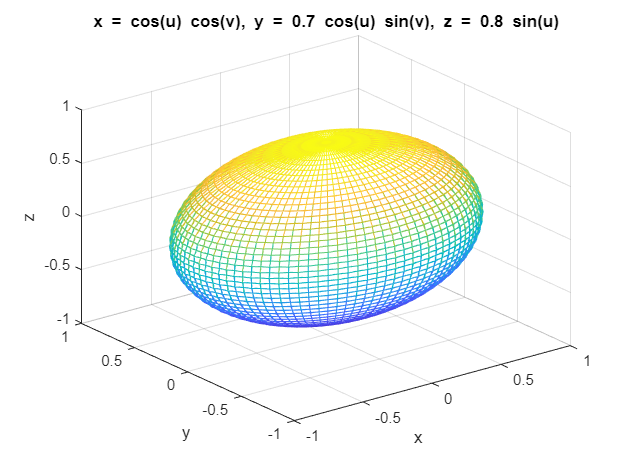

ezsurf('cos(u) .* cos(v)','0.7 * cos(u) .* sin(v)','0.8 * sin(u)', [-2 * pi, 2 * pi])

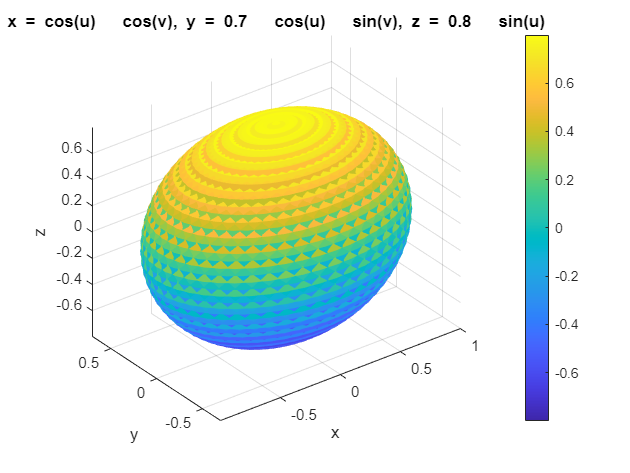

axis equal
colormap default
colorbar
shading flat
axis equal

## Задание 6.12

Построить график функции двух переменных на прямоугольной области определения.

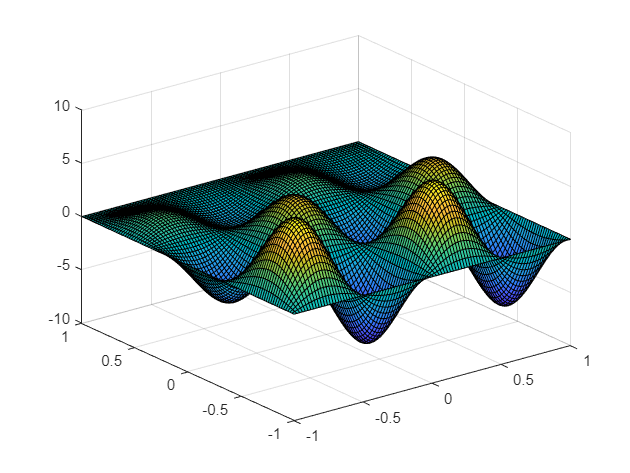

% а)
% x = -1:0.01:1;
% y = 0:0.01:1;
figure
[x, y] = meshgrid(linspace(-1, 1, 100));
z = 4 * sin(2 * pi * x) .* cos(1.5 * pi * y) .* (y - 1);
surf(x, y, z)

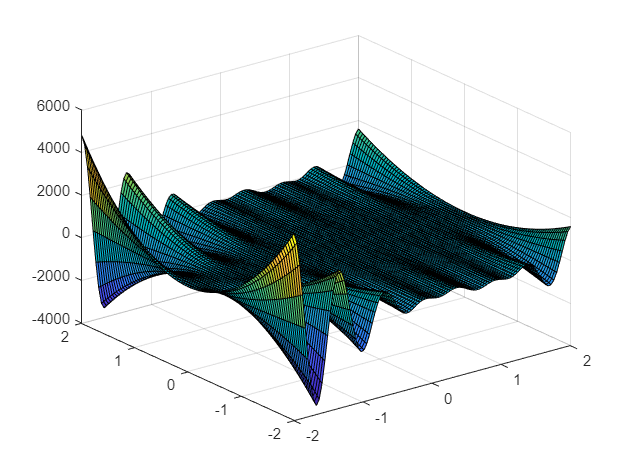

% б)
% x = -1:0.01:1;
% y = -2:0.01:2;
figure
[x, y] = meshgrid(linspace(-2, 2, 100));
z = -exp(- y .^ 2) - y .* 2 * cos(3 * pi * x) .* (1 - x) .* x .* y;
surf(x, y, z)

## Задание 6.15

Построить траекторию движения точки на плоскости или в пространстве в течение времени t.

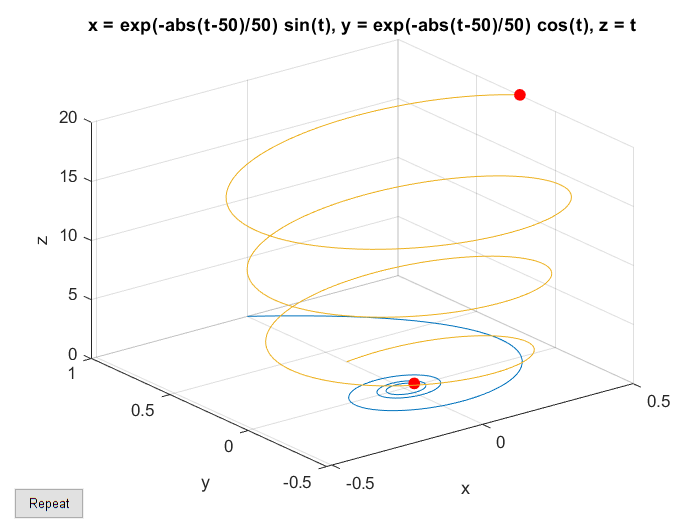

% а)
t = linspace(0, 10, 100);
x = @(t) sin(t)./(t + 1);
y = @(t) cos(t)./(t + 1);
z = @(t) 0;
ezplot3(x, y, z, [0, 20], 'animate')

% б)
t = linspace(0, 100, 1000);
x = @(t) exp(-abs(t - 50) / 50) .* sin(t);
y = @(t) exp(-abs(t - 50) / 50) .* cos(t);
z = @(t) t;
ezplot3(x, y, z, [0, 20], 'animate')

# Основы дескрипторной графики

## Пример 7.1

Функция get: вывод списка текущих значений свойств графического объекта.

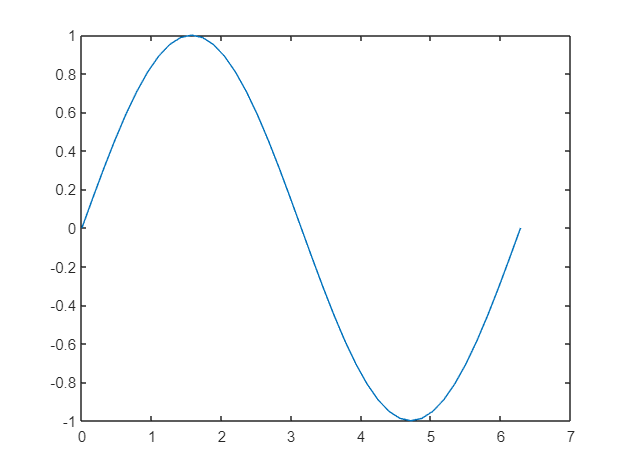

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.1571 0.3142 0.4712 0.6283 0.7854 0.9425 1.0996 1.2566 1.4137 1.5708 1.7279 1.8850 2.0420 2.1991 2.3562 2.5133 2.6704 2.8274 2.9845 3.1416 3.2987 3.4558 3.6128 3.7699 3.9270 4.0841 4.2412 4.3982 4.5553 4.7124 4.8695 5.0265 … ]
              YData: [0 0.1564 0.3090 0.4540 0.5878 0.7071 0.8090 0.8910 0.9511 0.9877 1 0.9877 0.9511 0.8910 0.8090 0.7071 0.5878 0.4540 0.3090 0.1564 1.2246e-16 -0.1564 -0.3090 -0.4540 -0.5878 -0.7071 -0.8090 -0.8910 -0.9511 -0.9877 -1 -0.9877 … ]

  Show <a href="matlab:if exist('h', 'var'), matlab.graphics.internal.getForDisplay('h', h, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('h'), end">all properties<

t = 0:pi / 20:2 * pi;
h = plot(t, sin(t)) % графический объект line

get(h)

    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [0 0.4470 0.7410]
             ColorMode: 'auto'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: '-'
         LineStyleMode: 'auto'
             LineWidth: 0.5000
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 … ]
            MarkerMode: 'auto'
            MarkerSize: 6
                Parent: [1

## Пример 7.2

Графические объекты и их свойства. Функция set: установка новых значений свойств графических объектов.

X = linspace(-pi / 2, 3 * pi); % 100 точек по умолчанию
Y = [sin(X); cos(X)];
h1 = plot(X, Y)'

h1 =   1×2 Line array:

    Line    Line


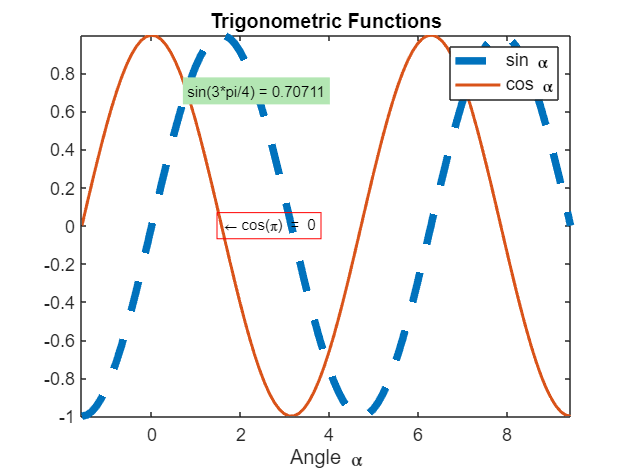

set(h1(1), 'linewidth', 5, 'linestyle', '--')
set(h1(2), 'linewidth', 2)
h2 = title('Trigonometric Functions');
xlabel('Angle \alpha', 'fontsize', 12);
h3 = legend(['sin \alpha'; 'cos \alpha']);
set([h2, h3, gca], 'fontsize', 12);
text(3*pi/4, sin(3*pi/4), ['sin(3*pi/4) = ', num2str(sin(3*pi/4))], 'HorizontalAlignment', 'center', 'BackgroundColor', [.7 .9 .7]);
text(pi/2, cos(pi/2), '\leftarrowcos(\pi) = 0', 'HorizontalAlignment', 'left', 'EdgeColor', 'red');
axis tight

## Задания

## Задание 7.3

Установите новое значение по умолчанию, равное 2.5, для свойства «толщина линии» LineWidth графического объекта Line на уровне текущего графического окна.

set(gcf,'DefaultLineLineWidth',2.5)

Графические объекты и их свойства. Функция set: установка новых значений свойств графических объектов.

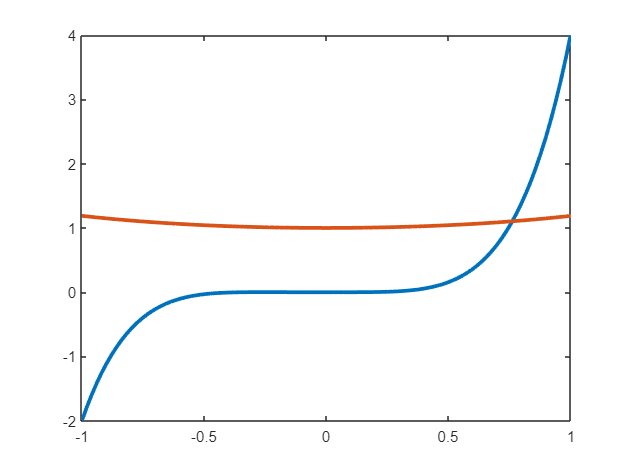

X = linspace(-1, 1);
Y = [X.^4+ 3 * X.^5; X ./ sin(X)];
plot(X, Y)

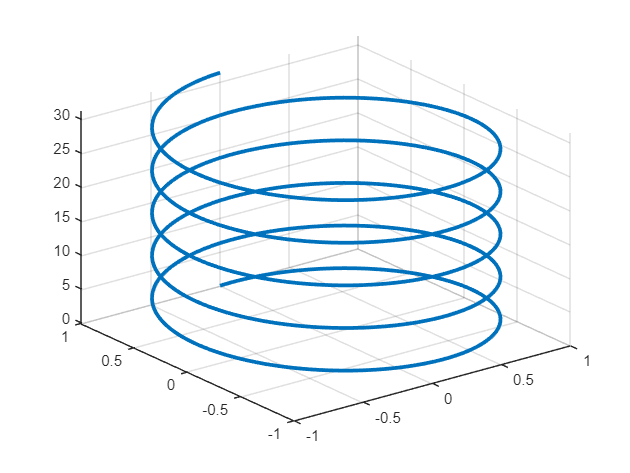

t = 0:pi / 50:10 * pi ;
x = sin(t);
y = cos(t);
plot3(x, y, t);
grid on

## Задание 7.4

Следующий код использует функцию line для добавления тени к нарисованному графику функции sin. 

Сначала при помощи функции plot рисуется линия, и ее дескриптор сохраняется в hline1. 

Затем добавляется более широкая и более светлая тень смещением по координате x. 

Наконец, первая линия помещается поверх второй.

По такой схеме нарисуйте 4 линии. 

Затем измените цвет самой тонкой линии на синий, стиль – на пунктирный, а ее толщину установите равной 2 points (1 point = 1/72 inch). 

Изменения выполните, используя дескриптор графического объекта.

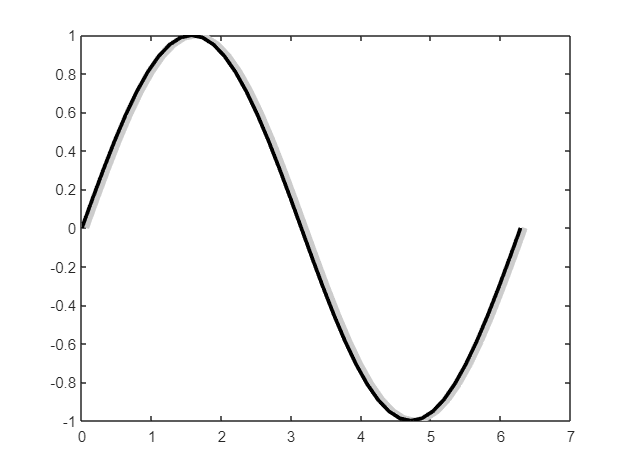

t = 0:pi/20:2 * pi;
hline1 = plot (t, sin(t), 'k');
hline2 = line (t + .06, sin(t), 'LineWidth', 4, 'Color', [.8 .8 .8]);
set (gca, 'Children', [hline1 hline2])

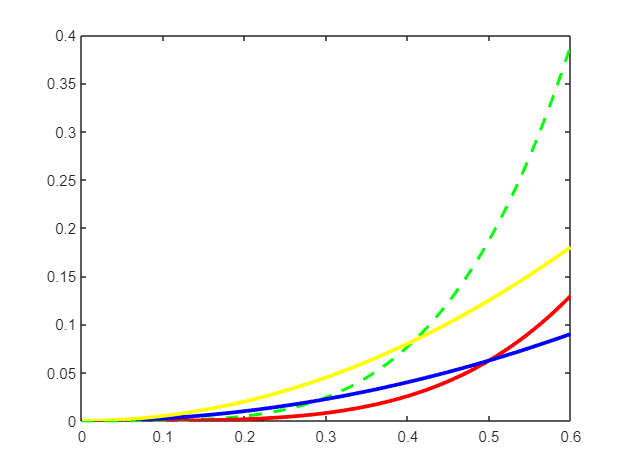

X = linspace(0, 0.6);
hline1 = plot (X, X .^ 2 / 2, 'y');
hline2 = line (X, X .^ 2 ./ 4, 'Color', 'Blue');
hline3 = line (X, X .^ 4, 'Color', 'Red');
hline4 = line (X, 3 * X .^ 4, 'Color', 'Green');
set(hline4, 'linewidth', 2, 'linestyle', '--')
set (gca, 'Children', [hline1 hline2 hline3 hline4])

## Задание 7.5

Введите команды, рисующие двадцать линий разных цветов сплошной линией толщиной 0.5 (свойства по умолчанию).

Затем найдите все линии красного цвета и удалите их. 

После этого найдите все линии синего цвета и измените их толщину на 2. 

Найдите все линии зеленого цвета и измените их стиль на штрихпунктирный.

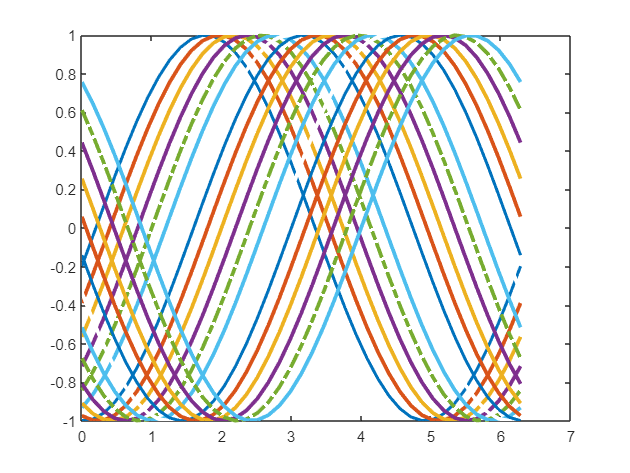

t = 0:pi/20:2*pi;
for i = 1:20 a(:, i) = sin(t - i / 5)'; end
h = plot(t, a);
set(h(7), 'Color', 'White')
set(h(14), 'Color', 'White')
set(h(1), 'linewidth', 2)
set(h(8), 'linewidth', 2)
set(h(15), 'linewidth', 2)
set(h(5), 'linestyle', '-.')
set(h(12), 'linestyle', '-.')
set(h(19), 'linestyle', '-.')